# Projective Distortion

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-03

## Review of Matrix Inverse

% define an inline function to evaluate and print out true or false
logicStr = {'False', 'True'};
PrtEqual = @(M1Str, M1, M2Str, M2) fprintf('%s and %s are equal: %s.', M1Str, M2Str, logicStr{isequal(M1, M2)+1});

% inverse of a 3 x 3 matrix
syms a b c d e f g h k;

H = [a b c; d e f; g h k];
inv_H = inv(H)

$$inv\_H = \begin{array}{l} \left(\begin{array}{ccc} \frac{f\,h-e\,k}{\sigma_{1}} & -\frac{c\,h-b\,k}{\sigma_{1}} & -\frac{b\,f-c\,e}{\sigma_{1}}\\ -\frac{f\,g-d\,k}{\sigma_{1}} & \frac{c\,g-a\,k}{\sigma_{1}} & \frac{a\,f-c\,d}{\sigma_{1}}\\ -\frac{d\,h-e\,g}{\sigma_{1}} & \frac{a\,h-b\,g}{\sigma_{1}} & -\frac{a\,e-b\,d}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a\,f\,h-b\,f\,g-c\,d\,h+c\,e\,g-a\,e\,k+b\,d\,k \end{array}$$

% Q: please check if this output is identical with the mathmatical equation in https://en.wikipedia.org/wiki/Invertible_matrix

for ii=1:3
    for jj=1:3
        subM = H;
        subM(ii,:)=[];
        subM(:,jj)=[];
        if mod(ii+jj,2)==0
            inv_H_new(jj,ii) = det(subM); % note that row and column are changed. (it is the same with transposing the matrix in the end)
        else
            inv_H_new(jj,ii) = -det(subM); % det(fliplr(subM))
        end
    end
end
inv_H_new = 1/det(H).*inv_H_new

$$inv\_H\_new = \begin{array}{l} \left(\begin{array}{ccc} \frac{f\,h-e\,k}{\sigma_{1}} & -\frac{c\,h-b\,k}{\sigma_{1}} & -\frac{b\,f-c\,e}{\sigma_{1}}\\ -\frac{f\,g-d\,k}{\sigma_{1}} & \frac{c\,g-a\,k}{\sigma_{1}} & \frac{a\,f-c\,d}{\sigma_{1}}\\ -\frac{d\,h-e\,g}{\sigma_{1}} & \frac{a\,h-b\,g}{\sigma_{1}} & -\frac{a\,e-b\,d}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a\,f\,h-b\,f\,g-c\,d\,h+c\,e\,g-a\,e\,k+b\,d\,k \end{array}$$

PrtEqual('inv_H', inv_H, 'inv_H_new', inv_H_new)

inv_H and inv_H_new are equal: True.

% Q: please check if this output is identical with the mathmatical equation in http://mathworld.wolfram.com/MatrixInverse.html

% affine matrix
syms a b c d e f;
HA = [a b c; d e f;0 0 1];
A = [a b;d e];
t = [c;f];

HA_new = [A t;0 0 1];
PrtEqual('HA', HA, 'HA_new', HA_new)

HA and HA_new are equal: True.


inv_HA = inv(HA);
inv_HA_new = [inv(A) -inv(A)*t;0 0 1];

% affine rectification
clear; 
syms l1 l2 l3
HH = [1 0 0;0 1 0;l1 l2 l3];
inv(HH)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ -\frac{l_{1}}{l_{3}} & -\frac{l_{2}}{l_{3}} & \frac{1}{l_{3}} \end{array}\right)$$

transpose(inv(HH))*[l1;l2;l3]

$$ans = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$


% conic form
syms k1 k2 k3 k4 v1 v2
K = [k1 k3; k2 k4];
v = [v1;v2];
KKT = K*transpose(K);
C = [KKT KKT*v;transpose(v)*KKT transpose(v)*KKT*v]

$$C = \begin{array}{l} \left(\begin{array}{ccc} {k_{1}}^{2}+{k_{3}}^{2} & k_{1}\,k_{2}+k_{3}\,k_{4} & \sigma_{2}\\ k_{1}\,k_{2}+k_{3}\,k_{4} & {k_{2}}^{2}+{k_{4}}^{2} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & v_{1}\,\sigma_{2}+v_{2}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{1}\,\left(k_{1}\,k_{2}+k_{3}\,k_{4}\right)+v_{2}\,\left({k_{2}}^{2}+{k_{4}}^{2}\right)\\ \sigma_{2}=v_{2}\,\left(k_{1}\,k_{2}+k_{3}\,k_{4}\right)+v_{1}\,\left({k_{1}}^{2}+{k_{3}}^{2}\right) \end{array}$$

### Review of linear algebra

Reference: Howard Anton & Rober C. Busby (2002) "Contemporary Linear Algebra"

- A nonempty set of vectors in $R^n$ is called a subspace of $R^n$ if it is closed under scalar multiplication and addition. 

- If  are vectors in $\mathbf{v_1}, \mathbf{v_2}, ....,\mathbf{v_s}$ are vectors in $R^n$, then the set of all linear combinations $$\mathbf{x} = t_1\mathbf{v_1}+t_s\mathbf{v_s}+.....+t_s\mathbf{v_s}$ is a subspace of $R^n$. The subspace $W
$of $R^n$ whose vectors satify this linear combination is called the ***span*** of $\mathbf{v_1}, \mathbf{v_2}, ....,\mathbf{v_s}$ and is denoted by $W = span \{ \mathbf{v_1}, \mathbf{v_2}, ....,\mathbf{v_s} \}$

- The row space of A, denoted by $row(A)
$, is the subspace of $R^n$ that is spanned by the row vectors of A. 

- The column space of A, denoted by $col(A)$, is the subspace of $R^n$ that is spanned by the col vectors of A. 

- The null space of A, denoted by $null(A)$, is the solution space of $A\mathbf{x}=0$. This is a subspace of $R^n$.

- The dimension of the row space of a matrix A is called the rank of A and is denoted by $rank(A)$; and the dimension of the null space of A is called the nullity of A and is denoted by $nullity(A)
$. 

- If $S$ is a nonempty set in $R^n$, then the orthogonal complement of $S
$, denoted by $S^{\bot}$, is defined to be the set of all vectors in $R^n$ that are orthogonal to every vector in $S$. 

- If $S$ is a nonempty set in $R^n$, then $S^{\bot}$ is a subspace of $R^n$. 

- If A is an m x n matrix, then the row space of A and the null space of A are orthogonal complements ($row(A)^{\bot}$ = $null(A$))

- If A is an m x n matrix, then $rank(A) + nullity(A)=n$

% null vectors in R^3
v1 = [1 0 0];
v2 = [10 0 0];

A = [v1;v2];
null(A)

ans =          0         0
    1.0000         0
         0    1.0000



% Find a basis for the subspace W of R^5 that is spanned by the vectors
v1 = [1 0 0 0 2];
v2 = [-2 1 -3 -2 -4];
v3 = [0 5 -14 -9 0];
v4 = [2 10 -28 -18 4];

A = [v1;v2;v3;v4];

rref(A)

ans =      1     0     0     0     2
     0     1     0     1     0
     0     0     1     1     0
     0     0     0     0     0


rank(A)

ans = 3

null_A = null(A)

null_A =     0.0617   -0.8923
    0.5760    0.0398
    0.5760    0.0398
   -0.5760   -0.0398
   -0.0308    0.4461



A*null_A(:,1)

ans = 	1.0e+-14 *

    0.0722
   -0.0652
   -0.1110
   -0.2456


A*null_A(:,2)

ans = 	1.0e+-15 *

    0.5551
   -0.8882
   -0.1318
    0.6661



rank(A)+size(null_A,2)

ans = 5

## Recovery of affine properties

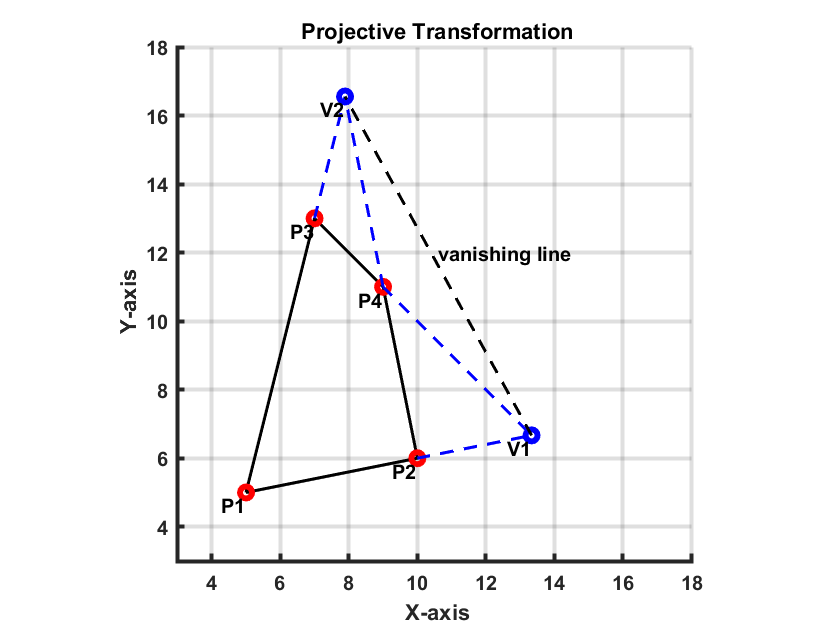

close all;

hom = @(x) [x;1];

p1 = [5 5]';
p2 = [10 6]';
p3 = [7 13]';
p4 = [9 11]';

Pt = [p1 p2 p4 p3];
Pth = [hom(p1), hom(p2) hom(p4) hom(p3)];

l1 = cross(hom(p1), hom(p2));
l2 = cross(hom(p3), hom(p4));
l3 = cross(hom(p1), hom(p3));
l4 = cross(hom(p2), hom(p4));

v1h = cross(l1, l2);
v2h = cross(l3, l4);
l_vanishing = cross(v1h, v2h);

figure(1);
line([Pt(1,:) Pt(1,1)], [Pt(2,:) Pt(2,1)],  'linewidth', 1.5, 'Color', 'k');hold on;
plot(Pt(1,:), Pt(2,:), 'or', 'linewidth', 3); 
text(Pt(1,:),Pt(2,:),{'P1','P2','P4','P3'},'horiz','right','vert','top','FontWeight','bold');

v1 = v1h(1:2)./v1h(3);
v2 = v2h(1:2)./v2h(3);

plot(v1(1), v1(2), 'ob', 'linewidth', 3);
plot(v2(1), v2(2), 'ob', 'linewidth', 3);

line([p4(1) v1(1)], [p4(2) v1(2)], 'Color', 'b', 'linewidth',  1.5, 'LineStyle', '--');
line([p2(1) v1(1)], [p2(2) v1(2)], 'Color', 'b', 'linewidth',  1.5, 'LineStyle', '--');
text(v1(1), v1(2), {'V1'},'horiz','right','vert','top','FontWeight','bold');

line([p4(1) v2(1)], [p4(2) v2(2)], 'Color', 'b', 'linewidth',  1.5, 'LineStyle', '--');
line([p3(1) v2(1)], [p3(2) v2(2)], 'Color', 'b', 'linewidth',  1.5, 'LineStyle', '--');
text(v2(1), v2(2), {'V2'},'horiz','right','vert','top','FontWeight','bold');

% vanishing line
line([v1(1) v2(1)], [v1(2) v2(2)], 'Color', 'k', 'linewidth',  1.5, 'LineStyle', '--');
text(mean([v1(1) v2(1)]), mean([v1(2) v2(2)]), {'vanishing line'},'horiz','left','vert','bottom','FontWeight','bold');

axis equal;grid on; hold off
title('\bf Projective Transformation');
xlabel('\bf X-axis');xlim([3 18]);
ylabel('\bf Y-axis');ylim([3 18]);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')


H = [1 0 0;0 1 0; l_vanishing']

H =            1           0           0
           0           1           0
        2136        1176      -36320


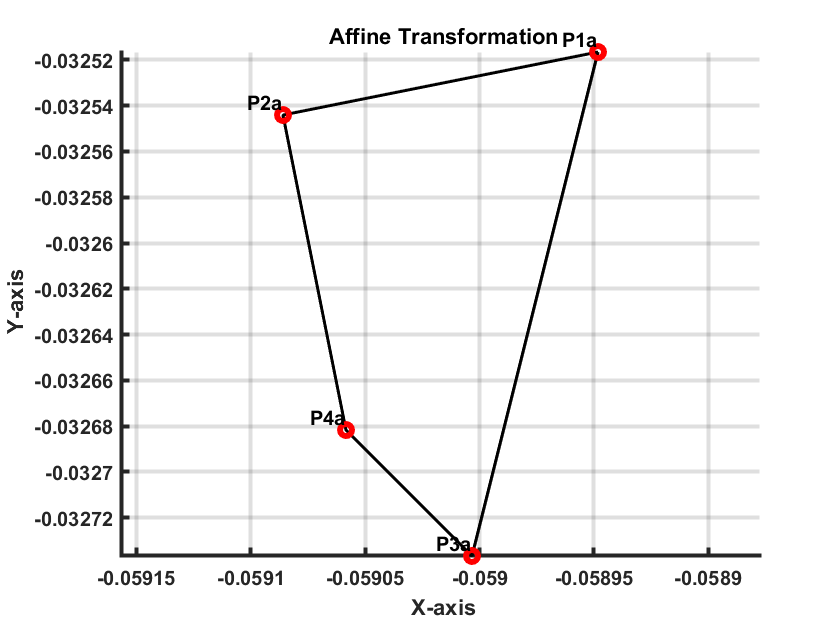


Pth_a = H*Pth;
Pt_a = bsxfun(@rdivide, Pth_a(1:2,:), Pth_a(3,:));

figure(2);
line([Pt_a(1,:) Pt_a(1,1)], [Pt_a(2,:) Pt_a(2,1)],  'linewidth', 1.5, 'Color', 'k');hold on;
plot(Pt_a(1,:), Pt_a(2,:), 'or', 'linewidth', 3); 
text(Pt_a(1,:),Pt_a(2,:),{'P1a','P2a','P4a','P3a'},'horiz','right','vert','bottom','FontWeight','bold');
axis equal;grid on; hold off
title('\bf Affine Transformation');
xlabel('\bf X-axis');
ylabel('\bf Y-axis');
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')

## Metric Rectification

% two-setp method
syms l1 l2 l3 s1 s2 s3 m1 m2 m3
lCm1 = [l1 l2 l3]*[s1 s2 0;s2 s3 0;0 0 0]*[m1;m2;m3]==0

$$lCm1 = m_{1}\,\left(l_{1}\,s_{1}+l_{2}\,s_{2}\right)+m_{2}\,\left(l_{1}\,s_{2}+l_{2}\,s_{3}\right)=0$$


[A,b] = equationsToMatrix(lCm1, [s1;s2;s3])

$$A = \left(\begin{array}{ccc} l_{1}\,m_{1} & l_{1}\,m_{2}+l_{2}\,m_{1} & l_{2}\,m_{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} 0 \end{array}\right)$$


% one-step method
syms l1 l2 l3 a b c d e f m1 m2 m3
Cd = [a b c;b d e;c e f];
lCm2 = [l1 l2 l3]*Cd*[m1;m2;m3]==0

$$lCm2 = m_{1}\,\left(a\,l_{1}+b\,l_{2}+c\,l_{3}\right)+m_{2}\,\left(b\,l_{1}+d\,l_{2}+e\,l_{3}\right)+m_{3}\,\left(c\,l_{1}+e\,l_{2}+f\,l_{3}\right)=0$$


[A,b] = equationsToMatrix(lCm2, [a;b;c;d;e;f])

$$A = \left(\begin{array}{cccccc} l_{1}\,m_{1} & l_{1}\,m_{2}+l_{2}\,m_{1} & l_{1}\,m_{3}+l_{3}\,m_{1} & l_{2}\,m_{2} & l_{2}\,m_{3}+l_{3}\,m_{2} & l_{3}\,m_{3} \end{array}\right)$$

$$b = \left(\begin{array}{c} 0 \end{array}\right)$$

## Point Correspondance for Estimating a Homography

syms h11 h12 h13 h21 h22 h23 h31 h32 h33
syms x y x_p y_p
H = [h11 h12 h13;h21 h22 h23;h31 h32 h33];
x = [x;y;1];
xp = [x_p;y_p;1];

Hx = H*x;
eqn1 = Hx(1)-xp(1)/xp(3)*Hx(3) == 0;
eqn2 = Hx(2)-xp(2)/xp(3)*Hx(3) == 0;

[A1, b1] = equationsToMatrix(eqn1, [h11;h12;h13;h21;h22;h23;h31;h32;h33])

$$A1 = \left(\begin{array}{ccccccccc} x & y & 1 & 0 & 0 & 0 & -x\,x_{p} & -x_{p}\,y & -x_{p} \end{array}\right)$$

$$b1 = \left(\begin{array}{c} 0 \end{array}\right)$$

[A2, b2] = equationsToMatrix(eqn2, [h11;h12;h13;h21;h22;h23;h31;h32;h33])

$$A2 = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & x & y & 1 & -x\,y_{p} & -y\,y_{p} & -y_{p} \end{array}\right)$$

$$b2 = \left(\begin{array}{c} 0 \end{array}\right)$$